clear all;
digitDatasetPath = fullfile(matlabroot,'toolbox','nnet','nndemos', ...
    'nndatasets','DigitDataset');
imds = imageDatastore('split_images', ...
    'IncludeSubfolders',true, ...
    'LabelSource','foldernames');
figure;
perm = randperm(10000,20);
for i = 1:20
    subplot(4,5,i);
    imshow(imds.Files{perm(i)});
end
labelCount = countEachLabel(imds)

labelCount = 32×2 table
    Label    Count
    _____    _____

      2      1225 
      3      1229 
      4      1229 
      5      1263 
      6      1192 
      7      1302 
      8      1237 
      9      1378 
      A      1208 
      B      1226 
      C      1264 
      D      1226 
      E      1290 
      F      1212 
      G      1255 
      H      1254 


img = readimage(imds,1);
size(img)

ans =     28    28


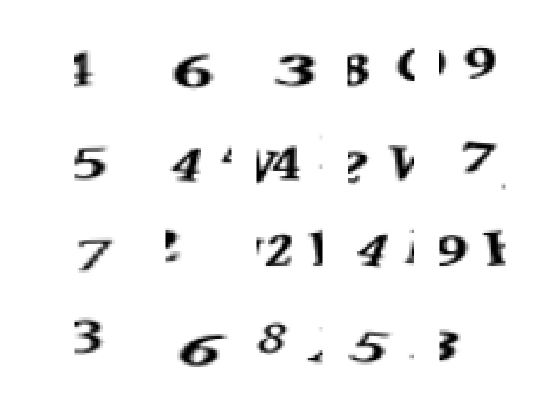

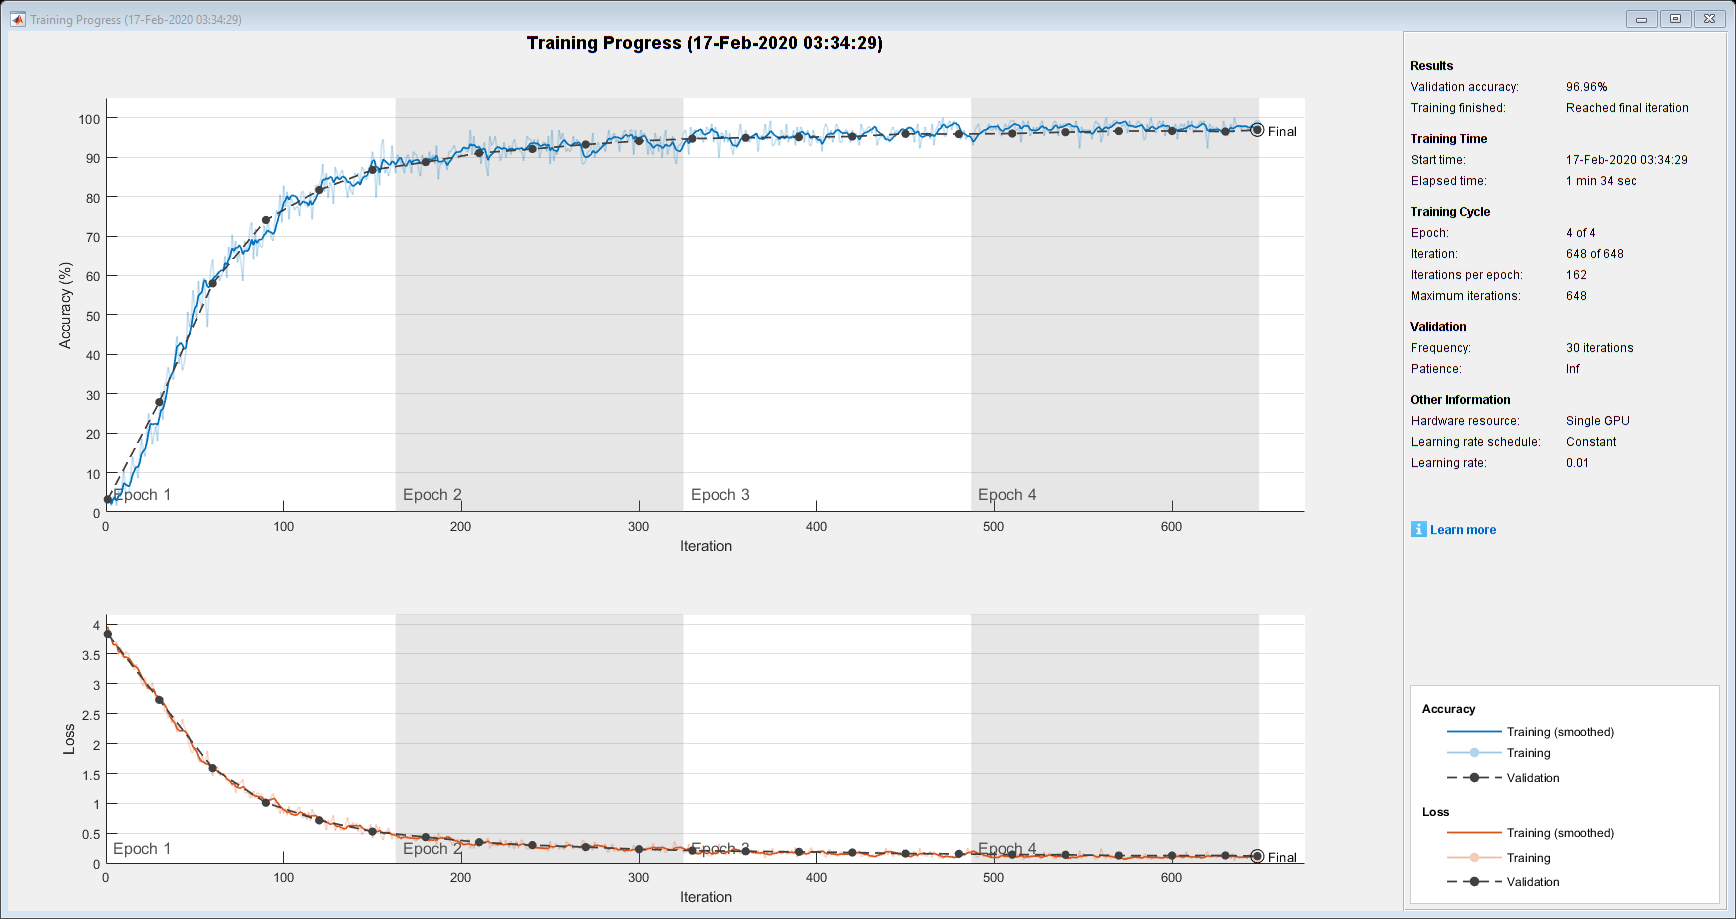

numTrainFiles = 650;
numTestingFiles = 100;
[imdsTrain,imdsTest,imdsValidation] = splitEachLabel(imds,numTrainFiles,numTestingFiles,'randomize');
layers = [
    imageInputLayer([28 28 1])
    
    convolution2dLayer(3,8,'Padding','same')
    batchNormalizationLayer
    reluLayer
    
    maxPooling2dLayer(2,'Stride',2)
    
    convolution2dLayer(3,16,'Padding','same')
    batchNormalizationLayer
    reluLayer
    
    maxPooling2dLayer(2,'Stride',2)
    
    convolution2dLayer(3,32,'Padding','same')
    batchNormalizationLayer
    reluLayer
    
    fullyConnectedLayer(32)
    softmaxLayer
    classificationLayer];
options = trainingOptions('sgdm', ...
    'InitialLearnRate',0.01, ...
    'MaxEpochs',4, ...
    'Shuffle','every-epoch', ...
    'ValidationData',imdsValidation, ...
    'ValidationFrequency',30, ...
    'Verbose',false, ...
    'Plots','training-progress');
net = trainNetwork(imdsTrain,layers,options);

YPred = classify(net,imdsTest);
YTest = imdsTest.Labels;

accuracy = sum(YPred == YTest)/numel(YTest)

accuracy = 0.9644